[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


lamdas = [.99, .999, .9999];
covs = [.001, .01, .1];
ir_len = 128;

N = length(lamdas);
S = length(covs);
n_iter = 1;
mses = zeros(N, S, n_iter);
preds = zeros(N, S, length(target));
out_wav = zeros(N, S, length(target));

min_mse = 100;
min_i = 0;
min_j = 0;

filter_order = ir_len * 2;

source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);
panel_ir = highpass(panel_ir, cutoff, fs);

% [ref, factor, target, panel_ir] = normalize_data(ref, target, panel_ir);

for i = 1:N
    lamda = lamdas(i);

    

    for j = 1:length(covs)
    
        cov = covs(j);

        fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov);
        fxrls.gpu = false;
        [pred_i, mses_i] = fxrls.learn(n_iter);
    
        mses(i, j, :) = mses_i;
        preds(i, j, :) = pred_i;
        out_wav(i, j, :) = fxrls.ref_filt;
        % preds(i, j, :) = denormalize_data(pred_i, factor);
        % out_wav(i, j, :) = denormalize_data(fxrls.ref_filt, factor);
        
        disp(mses_i)

        if mses_i(end) < min_mse
            min_mse = mses_i(end);
            min_i = i;
            min_j = j;
        end
    end

    disp('');

end

   7.6963e-09

   7.6964e-09

   7.6966e-09

   7.6801e-09

   7.2149e-09

   7.0566e-09

   1.1131e-07

   7.9279e-08

   4.3786e-08



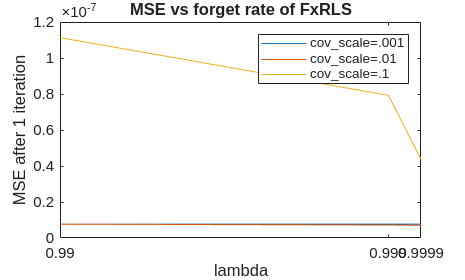

figure
plot(lamdas, mses(1, :, end))
hold on
plot(lamdas, mses(2, :, end))
hold on
plot(lamdas, mses(3, :, end))
hold off
set(gca, 'XScale', 'log')
xlim([lamdas(1), lamdas(end)])
xticks(lamdas)

legend("cov_scale=.001", "cov_scale=.01", "cov_scale=.1", 'Interpreter', 'None')
xlabel("lambda")
ylabel("MSE after 1 iteration")
title("MSE vs forget rate of FxRLS")

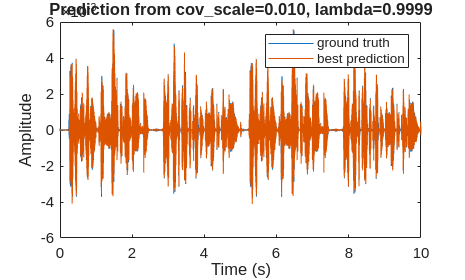

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, min_j, :)));
legend("ground truth", "best prediction")

title(sprintf('Prediction from cov_scale=%.3f, lambda=%.4f', covs(min_i), lamdas(min_j)), 'Interpreter', 'None')
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

min_i % ir_length

min_i = 2

min_j % step size

min_j = 3

% figure
% plot(squeeze(mses(min_i, min_j, :)))
% title('MSE from recorded reverb')
% xlabel('Iteration')
% ylabel('MSE')
% legend(sprintf('cov_scale=%d, lambda=%f', block_lens(min_i), step_sizes(min_j)), 'Interpreter', 'None')

save_cancel_clip(squeeze(out_wav(min_i, min_j, :)), sprintf('fxrls_cov=%.3f_lambda=%.4f', covs(min_i), lamdas(min_j)))
